% read an input 
train1_1 = imread('1.jpg');
train1_2 = imread('2.jpg');
train1_3 = imread('3.jpg');


## To Grayscale

train1_1 = rgb2gray(train1_1);
train1_2 = rgb2gray(train1_2);
train1_3 = rgb2gray(train1_3);

## Corner Detection

cm1_1 = detectHarrisFeatures(train1_1);
cm1_2 = detectHarrisFeatures(train1_2);
cm1_3 = detectHarrisFeatures(train1_3);


## Parameters

Nbest = 200;
ratio = 0.5;
threshold = 1.2*10^5;
n_max = 100;

## Test function

[x_best_1_1, y_best_1_1, cbest1_1] = ANMS(cm1_1, Nbest);
[x_best_1_2, y_best_1_2, cbest1_2] = ANMS(cm1_2, Nbest);
[x_best_1_3, y_best_1_3, cbest1_3] = ANMS(cm1_3, Nbest);

imshow(train1_1);
hold on;
scatter(y_best_1_1, x_best_1_1, 'r.')
hold off;

imshow(train1_2);
hold on;
scatter(y_best_1_2, x_best_1_2, 'r.')
hold off;

imshow(train1_3);
hold on;
scatter(y_best_1_3, x_best_1_3, 'r.')
hold off;

feature_vector1_1 = featureDescriptor(train1_1, x_best_1_1, y_best_1_1);
feature_vector1_2 = featureDescriptor(train1_2, x_best_1_2, y_best_1_2);
%feature_vector1_3 = featureDescriptor(train1_3, x_best_1_3, y_best_1_3);
%H = fspecial('gaussian', 40);
%f_vector1_1 = f_descriptor(cbest1_1,train1_1,H);
%f_vector1_2 = f_descriptor(cbest1_2,train1_2,H);

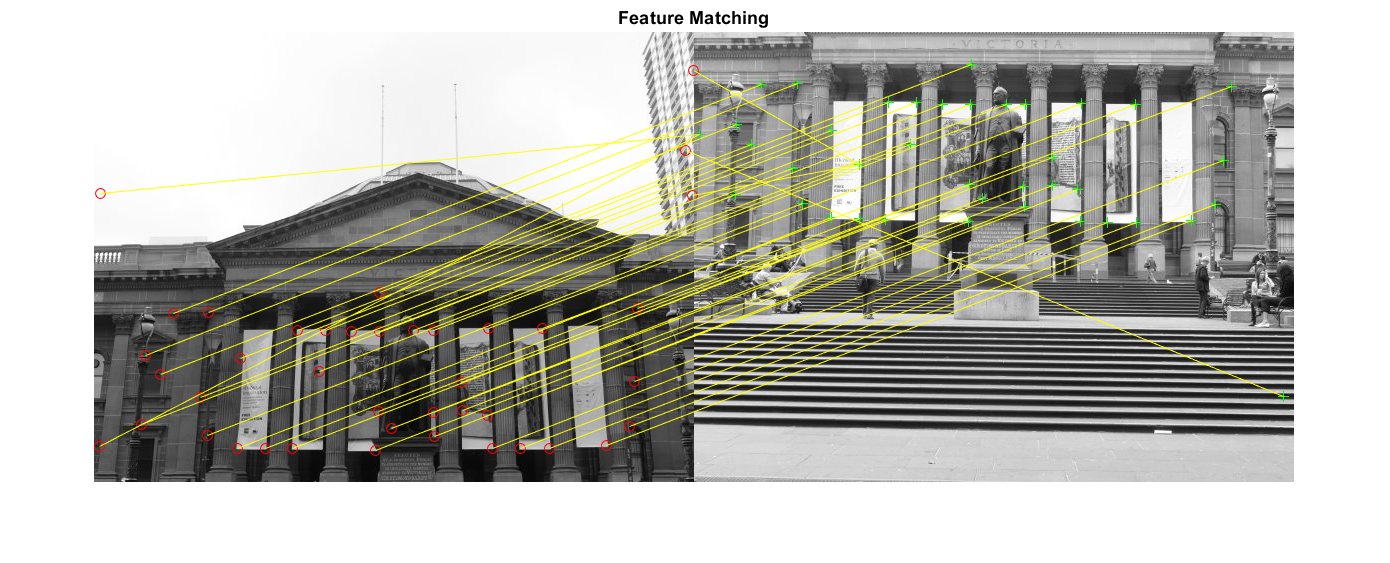

ratio = 0.5;
[matched_points1, matched_points2] = featureMatching(cbest1_1, cbest1_2, feature_vector1_1, feature_vector1_2, ratio);
%[matched_points1, matched_points3] = featureMatching(cbest1_1, cbest1_3, feature_vector1_1, feature_vector1_3, ratio);

figure; 
ax = axes;
%showMatchedFeatures(train1_1, train1_3, matched_points1, matched_points3, 'montage');
showMatchedFeatures(train1_1, train1_2, matched_points1, matched_points2, 'montage');
title(ax, 'Feature Matching');

%legend(ax, 'Matched points 1','Matched points 2');

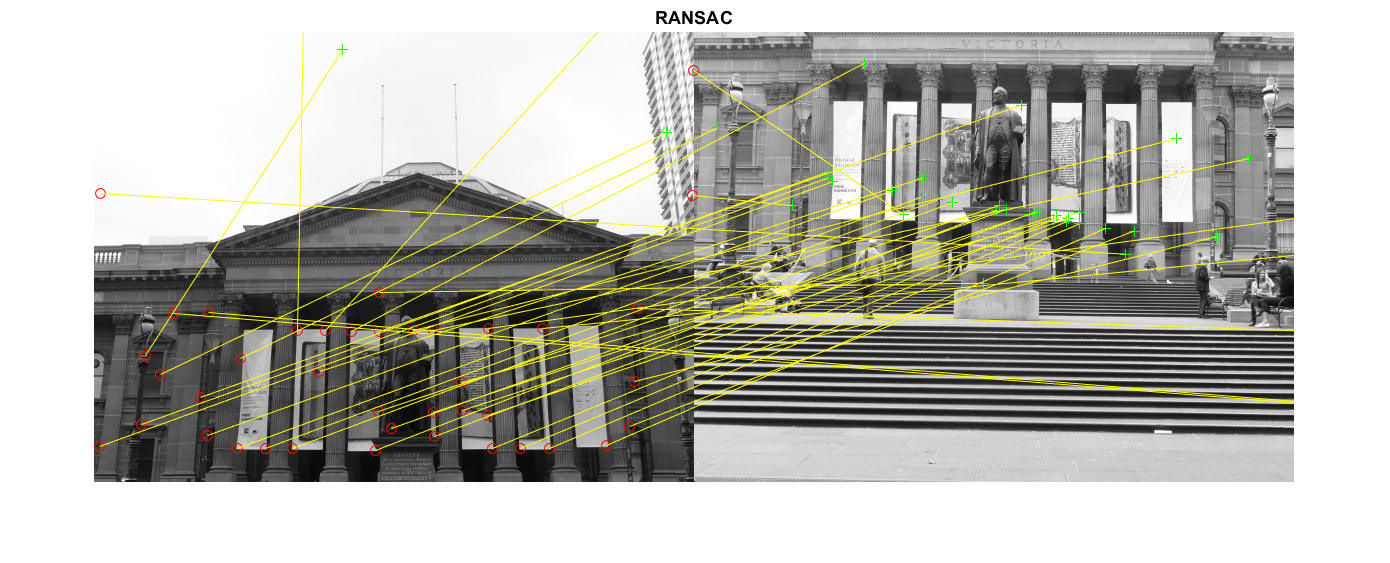

threshold = 1.2*10^5;
[match_1, match_2] = RANSAC(matched_points1, matched_points2, threshold, n_max);
figure; 
ax = axes;
showMatchedFeatures(train1_1, train1_2, match_1, match_2, 'montage');%, 'Parent', ax);
title(ax, 'RANSAC');

%legend(ax, 'Matched points 1','Matched points 2');

## Feature Descriptor

function feature_vector = featureDescriptor(train, x_best, y_best)
H = fspecial('gaussian', 40);
train = padarray(train, [20 20], 0, 'both');
feature_vector = zeros(64, size(x_best, 2));

for i = 1:size(x_best, 2)
%      x_left = max(x_best(i) - 20, 1);
%      x_right = min(x_best(i) + 20, size(train, 1));
%      y_top = max(y_best(i) - 20, 1);
%      y_bottom = min(y_best(i) + 20, size(train, 2));
     %new_matrix = train(x_left:x_right , y_top:y_bottom);
    new_matrix = train(x_best(i):x_best(i) + 40, y_best(i):y_best(i) + 40);
    new_matrix = im2double(new_matrix);
    convol_matrix = imfilter(new_matrix, H, 'conv');
    resized_matrix = imresize(convol_matrix, [8, 8]);
    resized_vector = double(resized_matrix(resized_matrix < inf));
    feature_vector(:,i) = (resized_vector - mean(resized_vector))/std(resized_vector);
end
end

## Feature Matching

function [matched_points1, matched_points2] = featureMatching(I1, I2, feature_vector1, feature_vector2, ratio)
k = 1;
for i = 1:size(feature_vector1, 2)
    smallest = inf;
    second_smallest = inf;
    for j = 1:size(feature_vector2, 2)
        d = norm(feature_vector1(:, i) - feature_vector2(:, j))^2;
        if(d < smallest)
            second_smallest = smallest;
            smallest = d;
            index = j;
        elseif (d < second_smallest && d ~= smallest)
            second_smallest = d;
        end
    end
    if smallest/second_smallest < ratio
        matched_points1(k, :) = [I1(2, i), I1(1, i)];
        matched_points2(k, :) = [I2(2, index), I2(1, index)];
        k = k + 1;
    end
end
end

## RANSAC 1

function [match_1, match_2] = RANSAC(matched_points1, matched_points2, threshold, n_max)
X = zeros(4,1);
Y = zeros(4,1);
x = zeros(4,1);
y = zeros(4,1);
percentage = 0;
j = 0;

while j <= n_max && percentage < 90
    for i = 1:4
        r = randi(size(matched_points1, 1));
        X(i, 1) = matched_points1(r, 1); %source
        Y(i, 1) = matched_points1(r, 2);
        x(i, 1) = matched_points2(r, 1); %dest
        y(i, 1) = matched_points2(r, 2);
    end
    
    H = est_homography(x, y, X, Y);
    [x1, y1] = apply_homography(H, matched_points1(:, 1), matched_points1(:, 2));    
    SSD(:, 1) = matched_points2(:, 1) - x1;
    SSD(:, 2) = matched_points2(:, 2) - y1;
    SSD_n = SSD(:, 1) + SSD(:, 2);
    SSD_n = SSD_n.^2;
    if size(SSD_n(SSD_n < threshold), 1)/size(SSD_n, 1) * 100 > percentage 
        percentage = size(SSD_n(SSD_n < threshold), 1) / size(SSD_n, 1) * 100;
        inliers = find(SSD_n < threshold);
    end
    j = j + 1;
end

inliers_1 = matched_points1(inliers, :);
inliers_2 = matched_points2(inliers, :);

H = est_homography(inliers_2(:, 1), inliers_2(:, 2), inliers_1(:, 1), inliers_1(:, 2));

[X2, Y2] = apply_homography(H, inliers_1(:, 1), inliers_1(:, 2));  
match_1 = inliers_1;
%match_2 = inliers_2;
match_2 = [X2 Y2];
%[X2, Y2] = apply_homography(H,inliers_2(:, 1), inliers_2(:, 2));  
%match_2 = [X2 Y2];
end

## RANSAC 2

function [match_1, match_2] = RANSAC(matched_points1, matched_points2, threshold, n_max)
X = zeros(4,1);
Y = zeros(4,1);
x = zeros(4,1);
y = zeros(4,1);
percentage = 0;
j = 0;

while j <= n_max && percentage < 90
    for i = 1:4
        r = randi(size(matched_points1, 1));
        X(i, 1) = matched_points1(r, 1); %source
        Y(i, 1) = matched_points1(r, 2);
        x(i, 1) = matched_points2(r, 1); %dest
        y(i, 1) = matched_points2(r, 2);
    end
    
    H = est_homography(x, y, X, Y);
    [x1, y1] = apply_homography(H, matched_points1(:, 1), matched_points1(:, 2));    
    SSD(:, 1) = matched_points2(:, 1) - x1;
    SSD(:, 2) = matched_points2(:, 2) - y1;
    SSD_n = SSD(:, 1) + SSD(:, 2);
    SSD_n = SSD_n.^2;
    if size(SSD_n(SSD_n < threshold), 1)/size(SSD_n, 1) * 100 > percentage 
        percentage = size(SSD_n(SSD_n < threshold), 1) / size(SSD_n, 1) * 100;
        inliers = find(SSD_n < threshold);
    end
    j = j + 1;
end

inliers_1 = matched_points1(inliers, :);
inliers_2 = matched_points2(inliers, :);

H = est_homography(inliers_2(:, 1), inliers_2(:, 2), inliers_1(:, 1), inliers_1(:, 2));

[X2, Y2] = apply_homography(H, inliers_1(:, 1), inliers_1(:, 2));  
match_1 = inliers_1;
%match_2 = inliers_2;
match_2 = [X2 Y2];
%[X2, Y2] = apply_homography(H,inliers_2(:, 1), inliers_2(:, 2));  
%match_2 = [X2 Y2];
end

## ANMS

function [x_best,y_best, c_best] = ANMS(cm,Nbest)

lm = imregionalmax(cm);


[x,y] = find(lm);

N_Strong = size(x,1);

r = inf(1,N_Strong);
ED = 0;

for i = 1:N_Strong
    for j = 1:N_Strong
        if cm(x(j),y(j)) > cm(x(i),y(i))
           ED =  (x(j)-x(i))^2 + (y(j)-y(i))^2;
           if ED < r(i)
              r(i) = ED;
           end 
        end
    end
end    

[sort_r,index] = sort(r,'descend');
c_best = zeros(2,Nbest);

for i = 1:Nbest
    c_best(1,i) = x(index(i)); 
    c_best(2,i) = y(index(i));
end

x_best = c_best(1,:);
y_best = c_best(2,:);
end
